# Frequency Steganography

Pilih gambar masukan untuk diproses:

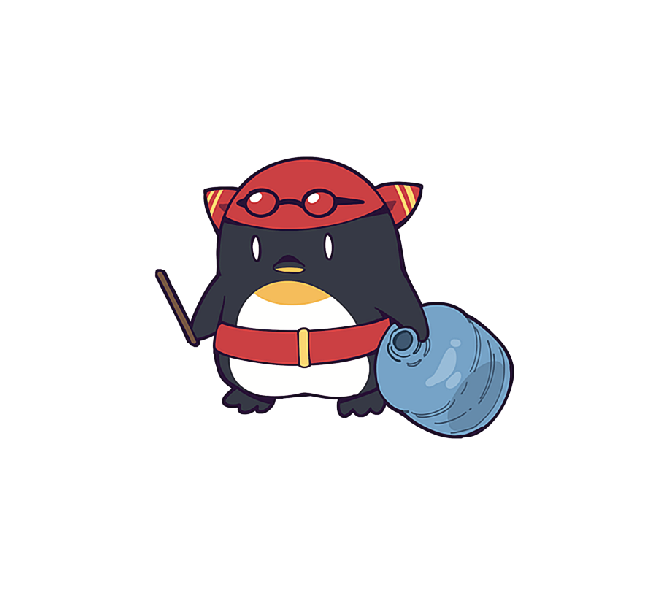

filename = "D:\Github\frequency-steganography\images\pemaloe.png";
message = "secret";
data = double(char(message));
data = [data, 0, 0, 0, 0];
im = imread(filename);
imshow(im);

### FFT based

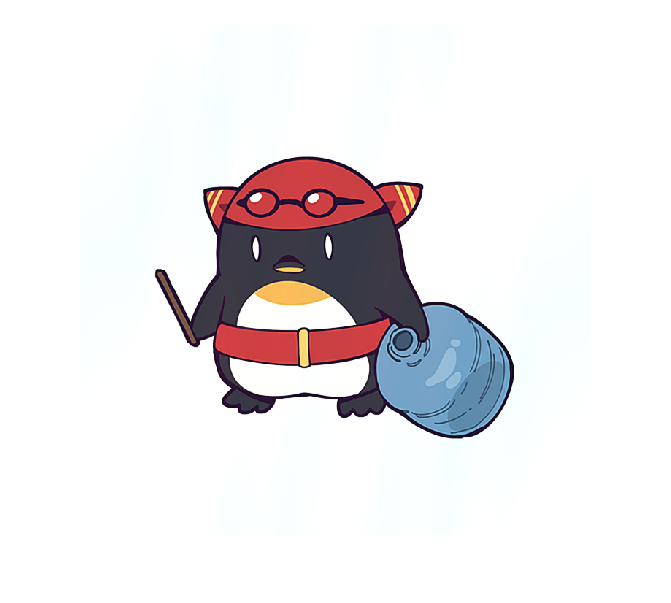

red = im(:, :, 1);
arr = fft2(red);
compl = imag(arr);
arr = real(arr);
r = size(arr, 1);
c = size(arr, 2);
for i = 1:size(data, 2)
    arr(r, c) = data(1, i);
    c = c - 1;
    if c == 0
        c = size(arr, 2);
        r = r - 1;
    end
end
newfftred = arr + 1i * compl;
newred = real(ifft2(newfftred));
newim = im;
newim(:, :, 1) = newred;
imshow(newim);

imsave;

### DCT Based

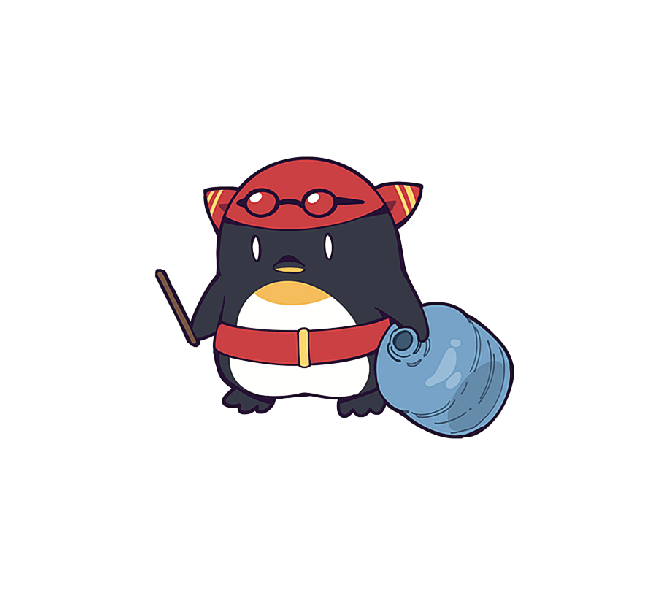

red = im(:, :, 1);
arr = dct2(red);
r = size(arr, 1);
c = size(arr, 2);
for i = 1:size(data, 2)
    arr(r, c) = data(1, i);
    c = c - 1;
    if c == 0
        c = size(arr, 2);
        r = r - 1;
    end
end
newred = idct2(arr);
newim = im;
newim(:, :, 1) = newred;
imshow(newim);

imsave;